# Coefficients of Restitution

[Coefficient of restitution](https://en.wikipedia.org/wiki/Coefficient_of_restitution) is defined as $C_r =\frac{u}{v}$where v is the velocity before a collision and u is the velocity after.

## Setup Parameters

H_0 = 10; % meters
V_0 = 25; % m/s
G = -9.8; % m/s^2
CR = .7;

dt = .01;
T = 0 : dt : 20; % secons
H = zeros(1,length(T)); % meters
V = zeros(1,length(T)); % m/s

H(1) = H_0;
V(1:end) = V_0;

## Simulate trajectory

for i = 2:length(T)
    V(i) = V(i - 1) + G * dt;
    H(i) = H(i - 1) + V(i) * dt;
    if(H(i) <= 0)
        V(i) = - V(i) *CR;
        H(i) = 0;
    
    end
end

## Plot Ball's Path and Velocity

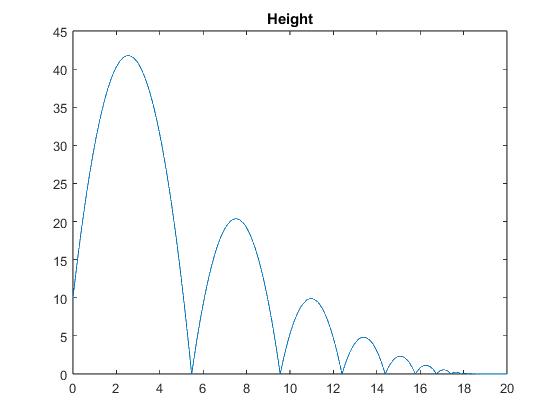

plot(T,H);
title("Height");

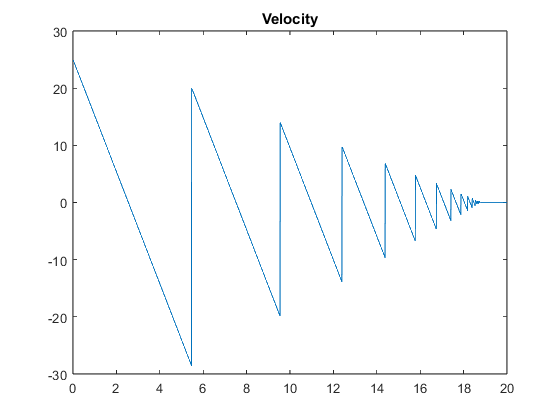

plot(T,V);
title("Velocity");